## AAE 440 PS9 Problem 3

clear all; close all; clc;
fdir = 'C:\Users\Tomo\Desktop\studies\2020-Spring\AAE440\MATLAB\outputs\HW9';
set(groot, 'defaulttextinterpreter','latex');  
set(groot, 'defaultAxesTickLabelInterpreter','latex');  
set(groot, 'defaultLegendInterpreter','latex');

% Defining System Properties
I       = 400;              % transverse moment of inertia [kg m2] 
J       = 100;              % axial moment of inertia      [kg m2] 
gamma0  = 8;                % Initial perturbation  [deg]
rev     = 0:0.001:2;        % Integration revolutions

% spin factor
k       = [-40, -15, 6, 12, 30, 80]; 


### (d)

% Characteristic Roots for different spin factor
lambda = zeros(6,6);
for i = 1:length(k)
    lambda(:,i) = eigenvalues(I,J,k(i));
end
res_array = [lambda(:,1) lambda(:,2) lambda(:,3) ...
             lambda(:,4) lambda(:,5) lambda(:,6)];
res_table = array2table(res_array, "VariableNames",...
            {'k = -40','k = -15','k = 6','k = 12','k = 30','k = 80'});

% Finding bounds for stable k
k_neg = -15:0.0001:0;
k_neg_bound = 0;
for i = 1:length(k_neg)
    lambda = eigenvalues(I,J,k_neg(i));
    for j = 1:6
        if real(lambda(j)) <= 0
            continue
        else
            k_neg_bound = k_neg(i);
            break
        end
    end
    if k_neg_bound == k_neg(i)
        break
    end
end
k_pos = 30:-0.0001:0;
k_pos_bound = 0;
for i = 1:length(k_pos)
    lambda = eigenvalues(I,J,k_pos(i));
    for j = 1:6
        if real(lambda(j)) <= 0
            continue
        else
            k_pos_bound = k_pos(i);
            break
        end
    end
    if k_pos_bound == k_pos(i)
        break
    end
end
k_bound = [k_neg_bound, k_pos_bound];

### (e)

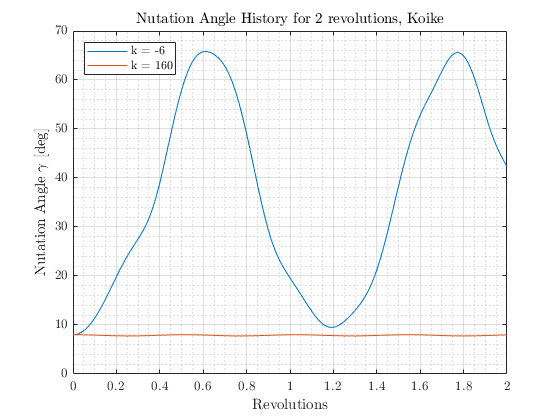

% Unstable and Potentially Stable k
k = [-6, 160];
for j = 1:2 
    % Repeat for different number of revolutions
    switch j
        case 1
        rev = 0:0.001:2;
        case 2
        rev = 0:0.001:10;
    end
    for i = 1:length(k)
        % Numerical Integration
        [rev, Nut, Prec] = Nut_Prec_History(rev,k(i),gamma0,I,J);
        % Plot Nutation
        figure(j);
            hold on;
            plot(rev, Nut, 'DisplayName',['k = ',num2str(k(i))])
    end

    fig = figure(j);
        grid on; grid minor; box on; lgd = legend; xlabel('Revolutions');
        lgd.Location = 'northwest';
        ylabel('Nutation Angle $\gamma$ [deg]')
        str = sprintf('Nutation Angle History for %d revolutions, Koike',rev(end));
        title(str)
        str = sprintf('P3e_Nutation_History_rev=%d.png',rev(end));
    saveas(fig, fullfile(fdir, str));
end

hold off; close all;

### Functions

function lambdas = eigenvalues(I,J,k)
    %{
    This function outputs EIGENVALUES PER OMEGA (orbital angular velocity) 
    to the characteristic equation
    %}
    
    x = J/I - 1;        % shape factor
    y = k - 1;          % spin factor
    Q = y + (1 + y)*x;  
    A = 3*x+Q^2+1;
    B = 3*x*Q+Q^2;
    % Eigenvalues
    lambdas = [ 0                           ;
                0                           ;
                sqrt((-A + sqrt(A^2-4*B))/2);
               -sqrt((-A + sqrt(A^2-4*B))/2);
                sqrt((-A - sqrt(A^2-4*B))/2);
               -sqrt((-A - sqrt(A^2-4*B))/2)];
end